%% Setup

Fs = 4 * 10^6; % Sampling rate
Tmax = 0.1; % Max time
N = Tmax * Fs; % Number of samples
B = 350 * 10^3; % Bandwidth
% Use these guys for plotting
t = linspace(0, Tmax-1/Fs, N); % Time variable
f = linspace(-Fs/2,Fs/2, N); % Frequency variable

Rs = 50 * 10^3; % Symbol rate in symbols/sec (baud)
Ns = Rs * Tmax; % Number of symbols to send
sps = Fs / Rs; % Number of samples per symbol
Ts = 1 / Rs;

fc = 1 * 10^6; % Carrier frequency in Hz

beta = 0.5; % RRC rolloff factor
span = 5; % number of symbols for length of filter impulse response
srrc = rcosdesign(beta, span, sps, 'sqrt'); % srrc transmitter/receiver impulse response

%% TX %%

%% Bits

bits = [0 1 0 0 0 0 1 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 1 1 0 0 1 1 1 0 1,...
       1 1 0 0 1 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0 0 1 1 1 0 0 1 1 0 0 1 0,...
       0 0 0 1 0 0 1 0 0 0 0 0 0 1 0 1 0 0 1 1 0 1 1 0 1 0 0 1 0 1 1 0 1 1,...
       0 1 0 1 1 1 0 1 0 1 0 1 1 0 1 1 0 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0,...
       0 1 1 0 1 0 0 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 0 1 0 0 0 0 0 0 1,...
       1 0 1 0 0 1 0 1 1 1 0 0 1 1 0 0 1 0 0 0 0 0 0 1 1 0 0 0 1 1 0 1 1 0,...
       1 1 1 1 0 1 1 0 1 1 0 1 0 1 1 1 0 0 0 0 0 1 1 0 1 1 0 0 0 1 1 0 0 1,...
       0 1 0 1 1 1 0 1 0 0 0 1 1 0 0 1 0 1];

%% Convert to BPSK Symbols

symbols = bits;
symbols(symbols == 0) = -1;

%% Append Packet Header

key = [1 1 1 -1 -1 -1 1 -1 -1 1 1 -1 1 -1 1];
header = repmat(key, 1, 3);

packet = [header symbols];
packet_length = length(packet)

packet_length = 301

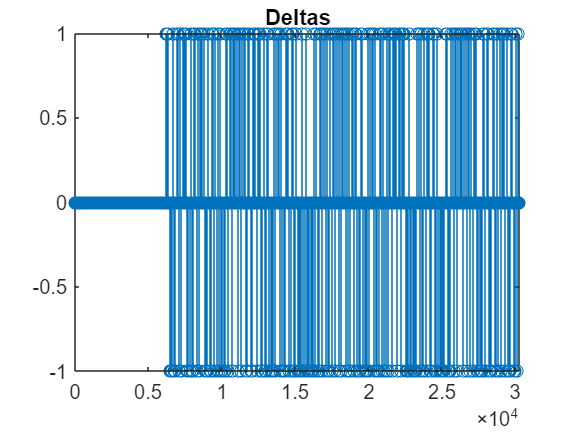


% here, we can repeat the packet or add zero-padding

% m = zeros(1, round(normrnd(100, 10)));
m = zeros(1, abs(round(normrnd(50, 10))));
packet = [m packet];

%% Convert to Upsampled Deltas

deltas = upsample(packet, sps);

figure()
stem(deltas)
title("Deltas")

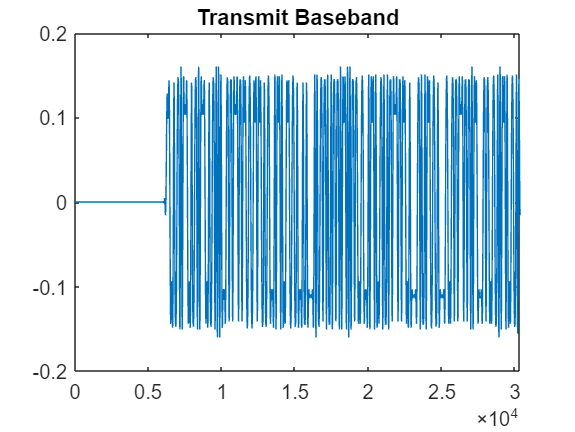

%% Apply Transmitter SRRC

transmit_bb = upfirdn(deltas, srrc, 1, 1); % convolve deltas with srrc
transmit_bb = transmit_bb(length(srrc)/2+0.5:end-length(srrc)/2+0.5); % alignment with deltas

% Symbol-Fractional Timing Offset
timing_offset_frac = 0.4; %
timing_offset_samps = round(timing_offset_frac * sps);
timing_offset_time = timing_offset_frac * Ts;
transmit_bb = [zeros(1, timing_offset_samps) transmit_bb];

figure()
plot(transmit_bb)
title("Transmit Baseband")

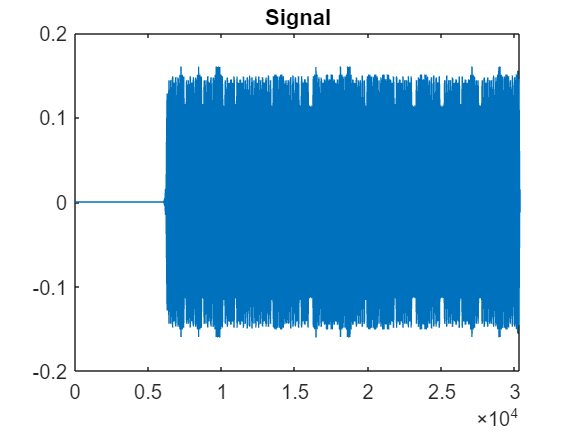

%% Carrier Modulation

carrier = exp(1j*2*pi*fc * t);

analytic = transmit_bb .* carrier(1:length(transmit_bb));

signal = real(analytic);

figure()
plot(signal)
title("Signal")

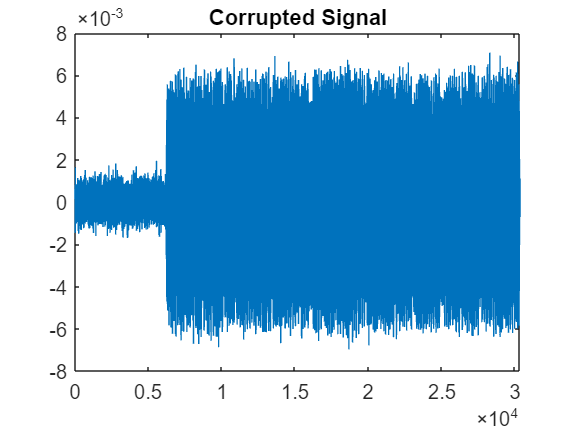

%% CHANNEL %%

%% Channel Filter, Impairments, and Noise

% Band-limited channel
s = tf('s');
Hc = B*s/(s^2 + s*B + fc^2);
Hd = c2d(Hc, 1/Fs, 'tustin');
[a, b] = tfdata(Hd);
signal = real(filter(a{:}, b{:}, signal));

% Non-ideal phase shift
phase = unifrnd(0, 2*pi);
signal = real(signal*exp(1i*phase));

% Frequency variation
frequency_variation = 10 * 10^3;

% Noise
noise_pwr = 0.0005;
noise = noise_pwr * randn(1, length(signal));
signal = signal + noise;
figure()
plot(signal)
title("Corrupted Signal")

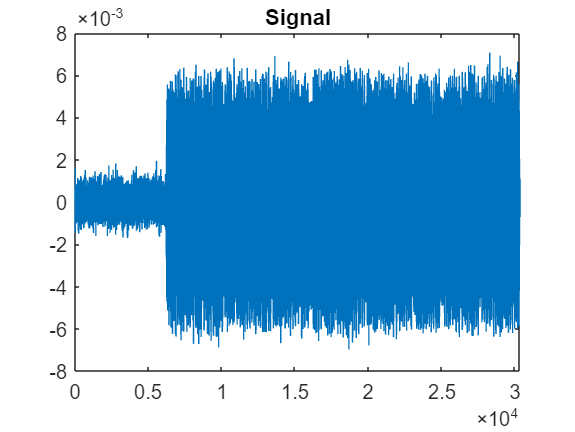

%% RX %%

%% Carrier Demodulation and Phase Tracking with Costas Loop

fr = fc + frequency_variation; % rx frequency initially guessed to match the tx frequency

theta = 0; % initial value
err_sum = 0;
Kp = 0.1;
Ki = 0.002;
I = zeros(1, length(transmit_bb));
Q = zeros(1, length(transmit_bb));
err = zeros(1, length(transmit_bb));


order = 5;
lp = designfilt('lowpassfir','FilterOrder',order,'CutoffFrequency',0.2*fc / Fs);


I_mod = zeros(1, length(transmit_bb));
Q_mod = zeros(1, length(transmit_bb));


plot(signal)
title("Signal")

figure()

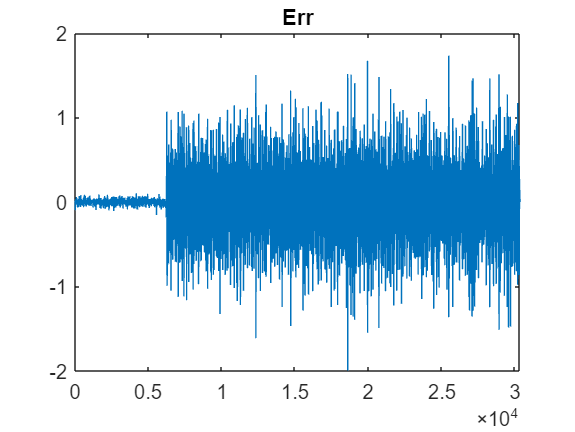

signal = normalize(signal);

for i = (1 + order):length(transmit_bb)
    %1) Demodulate
    I_mod(i) = signal(i) * 2 * cos(2 * pi * fr * t(i) + theta);
    Q_mod(i) = signal(i) * -2 * sin(2 * pi * fr * t(i) + theta);
 
    %2) Lowpass
    Ismoothed = filter(lp, I_mod(i-order:i));
    Qsmoothed = filter(lp, Q_mod(i-order:i));
    
    %3) Extract I and Q
    I(i) = Ismoothed(end);
    Q(i) = Qsmoothed(end);
    
    %4) Calculate Error
    err(i) = I(i) * Q(i);
    err_sum = err_sum + err(i);
    
    %5) Update Theta
    theta = theta + Kp * err(i) + Ki * err_sum;

end

receive_bb = I + 1j * Q;

plot(err)
title("Err")

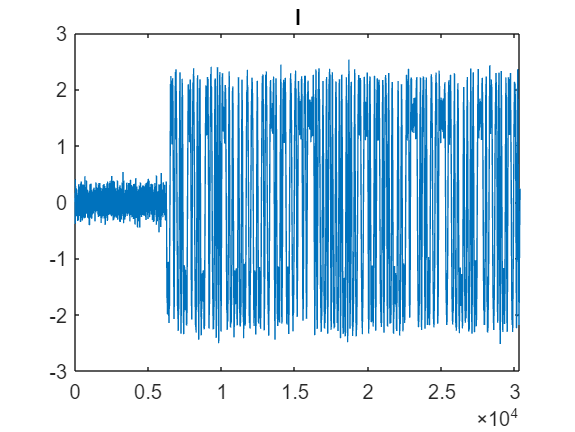

plot(I)
title("I")

figure()

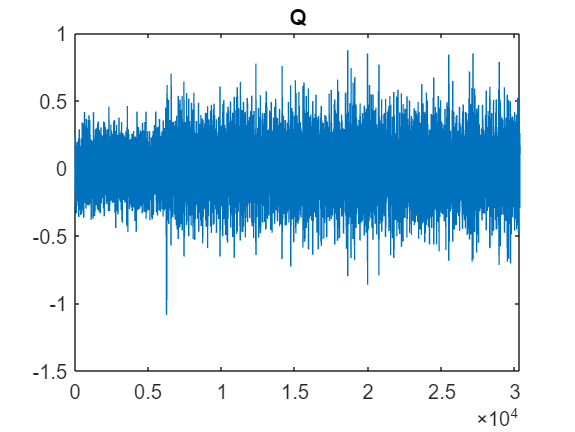

plot(Q)
title("Q")

figure()

%% Apply Receiver SRRC

received_samples = upfirdn(receive_bb, srrc, 1, 1); % convolve deltas with srrc
received_samples = received_samples(length(srrc)/2+0.5:end-length(srrc)/2+0.5);

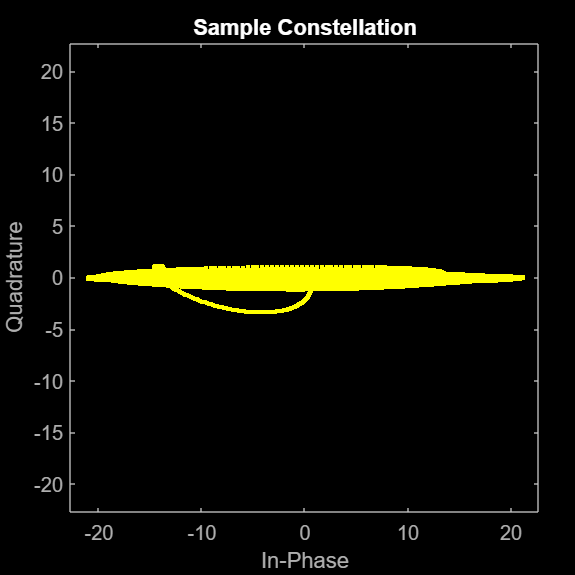

% We need timing recovery to pick out the 'correct' samples
% of the sample constellation to be our symbol-decision points.
% We want the eye diagram to be maximally open (--> maximal
% distance from the decision boundary), so we *roughly* choose
% samples around either distant endpoint
scatterplot(received_samples)
title("Sample Constellation")

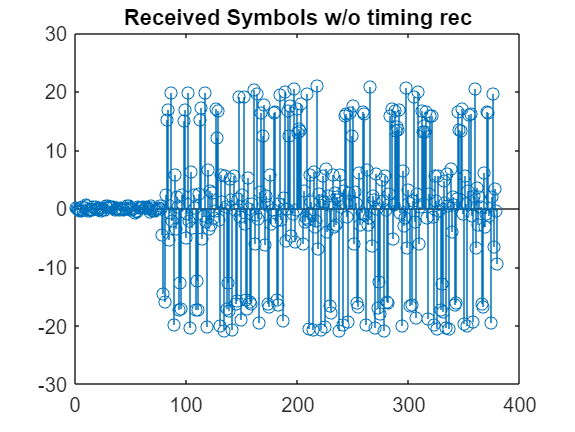

figure

% This is what we'd have without timing recovery
% aka just drawing naively every sps samples
received_symbols = received_samples(1:sps:end);
stem(real(received_symbols))
title("Received Symbols w/o timing rec")

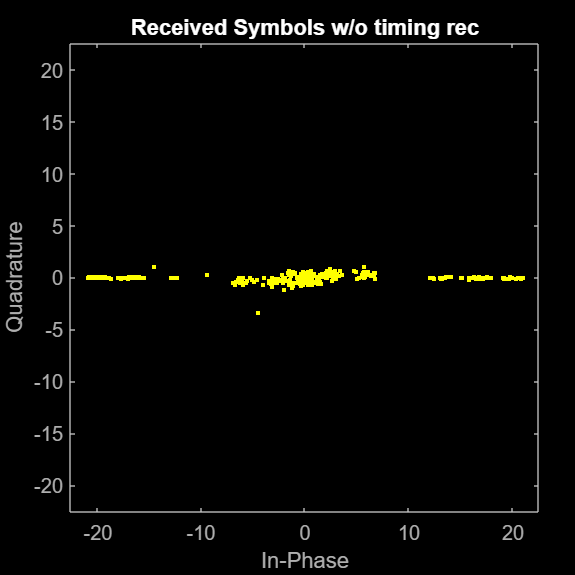

figure

scatterplot(received_symbols)
title("Received Symbols w/o timing rec")

figure

% Normalize input signal (would use an AGC in real system)
% ^Necessary for consistent PID tuning
received_samples = real(received_samples);
x = normalize(received_samples);

% Array Setup
i = 2;
err = zeros(1, ceil(length(x) / sps));
symbs = zeros(1, ceil(length(x) / sps));
tau = zeros(1, 1 + ceil(length(x) / sps));

% Apply SPS offset
sps_offset = 0;
sps = 80 + sps_offset;


% PID
Kp = 7.5;
Ki = 1.0; % observe how Ki smooths the oscillations before settling to a constant offset (but eventually goes unstable)
Kd = 0.0; % observe how Kd increases high frequency noise in the lock

% Draw first symbol -- no locking affects first symb, just draw naively
symbs(1) = x(1*sps);

% Begin locking
while i*sps + round(tau(i)) < length(x)
    
    % Gardner / ZC
    symbs(i) = x(i*sps + round(tau(i)));

    zc_samp = x(round((i - 1/2)*sps + tau(i)));
    curr_samp = x(i*sps + round(tau(i)));
    prev_samp = x(round((i - 1)*sps + tau(i-1)));

    % Gardner TED formula
    err(i) = zc_samp * (prev_samp - curr_samp);
    % Zero-Crossing TED formula
    % err(i) = zc_samp * (sign(prev_samp) - sign(curr_samp));
    % use comments to select the TED to be used

    tau(i+1) = tau(i) + Kp*err(i) + Ki*sum(err) + Kd*(err(i)-err(i-1));

    i = i + 1;
end

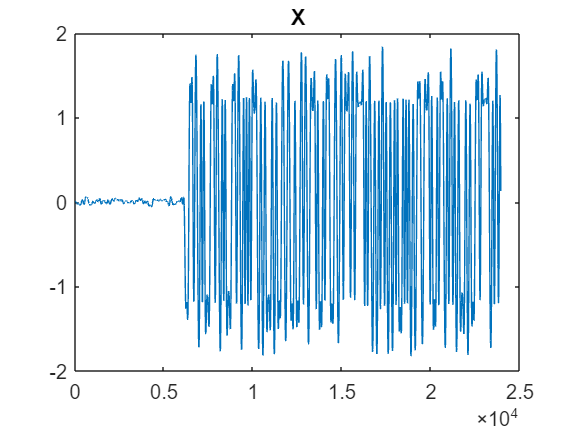

% Plotting for Timing Recovery
sps = 80;

start_symbol = 1;
% start_symbol = 1 for viewing locking onset
% start_symbol = 200 for viewing once locked
end_symbol = 300;

plot(x(start_symbol*sps:end_symbol*sps))
title("X")

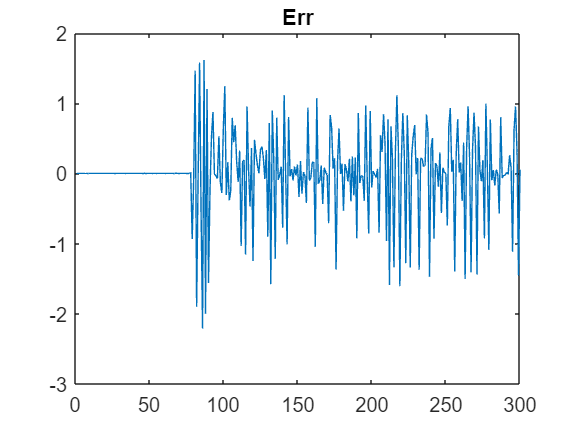

figure

plot(err(start_symbol:end_symbol))
title("Err")

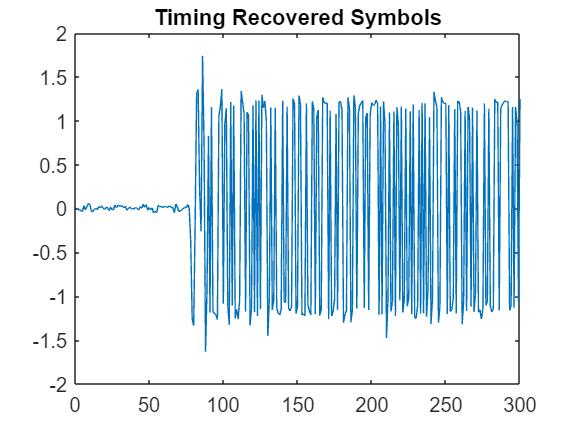

figure

plot(symbs(start_symbol:end_symbol))
title("Timing Recovered Symbols")

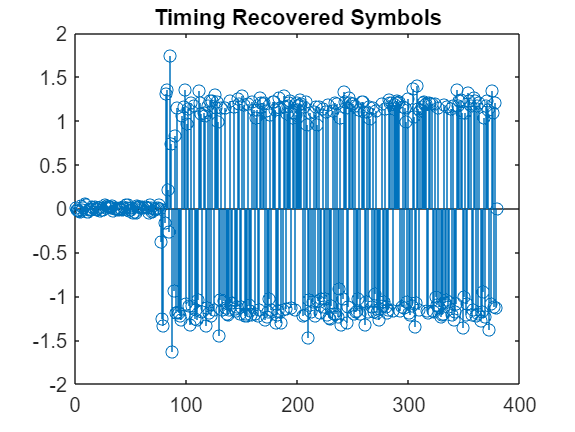

figure

stem(symbs)
title("Timing Recovered Symbols")

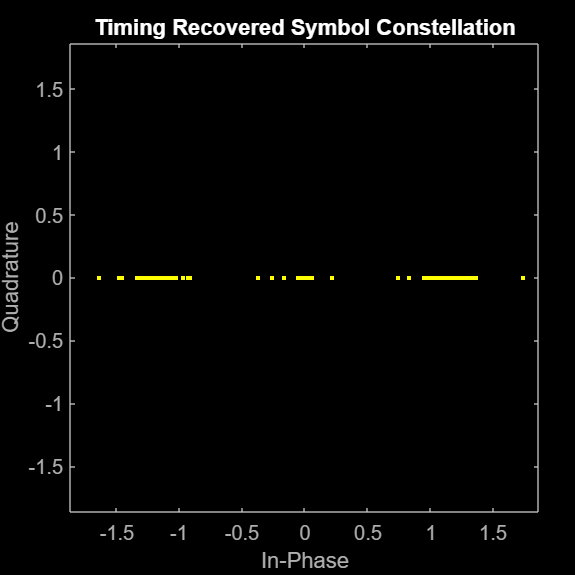

figure

scatterplot(symbs(start_symbol:end_symbol))
title("Timing Recovered Symbol Constellation")

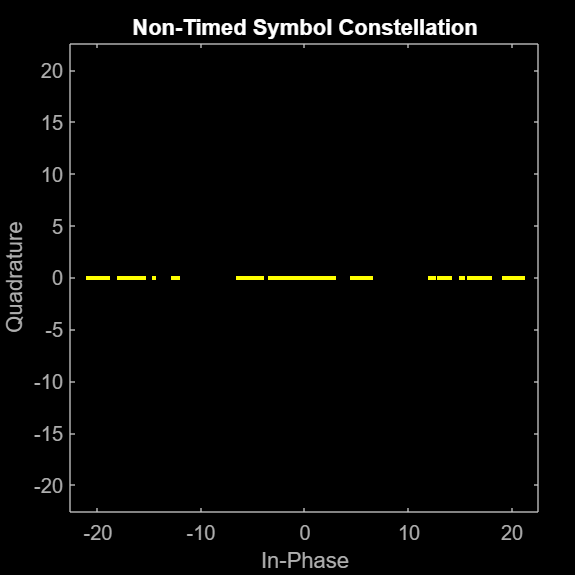

figure

scatterplot(received_samples(start_symbol*sps:sps:end_symbol*sps))
title("Non-Timed Symbol Constellation")

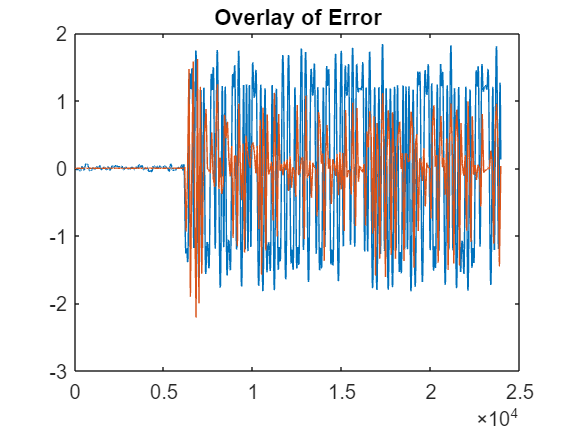

figure

plot(x(start_symbol*sps:end_symbol*sps))
hold on
interp_err = interp1(sps:sps:length(err)*sps, err, 0:length(err)*sps, 'linear');
plot(interp_err(start_symbol*sps:300*sps))
title("Overlay of Error")
hold off

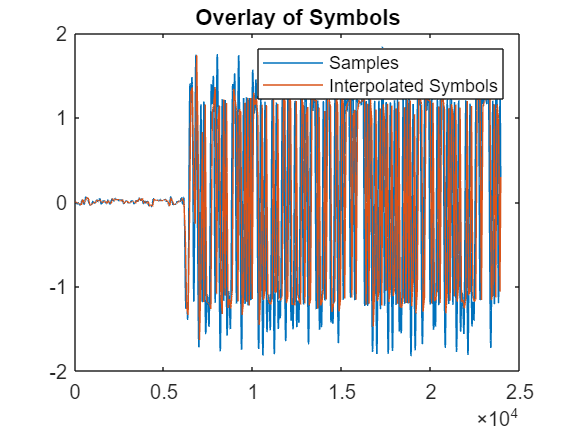

figure

plot(x(1*sps:end_symbol*sps))
hold on
interp_symbs = interp1(sps:sps:length(symbs)*sps, symbs, 0:length(symbs)*sps, 'linear');
%interp_symbs = upsample(symbs, sps);
plot(interp_symbs(1*sps-timing_offset_samps:end_symbol*sps-timing_offset_samps))
title("Overlay of Symbols")
legend("Samples", "Interpolated Symbols")
hold off

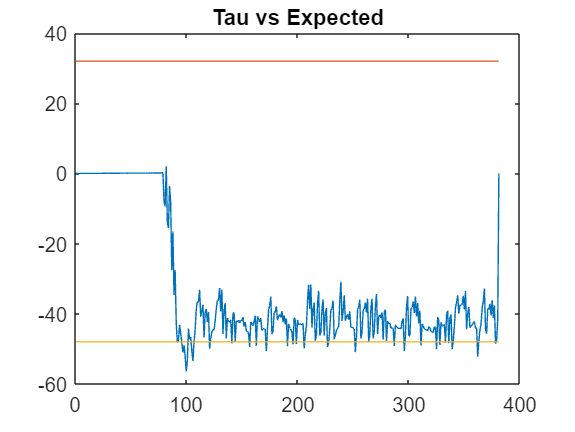

figure

plot(tau)
hold on
expected_tau1 = timing_offset_samps * ones(1, length(tau));
expected_tau2 = (timing_offset_samps - sps) * ones(1, length(tau));
title("Tau vs Expected")
plot(expected_tau1)
plot(expected_tau2)
hold off

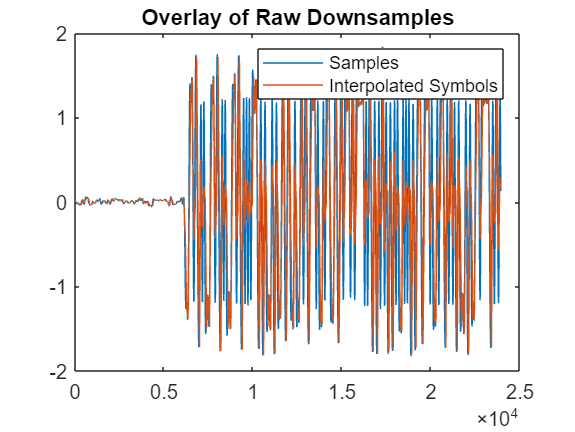

figure

plot(x(start_symbol*sps:end_symbol*sps))
hold on
x_downsample = [downsample(x,sps) zeros(1,30)];
interp_raw = interp1(0:sps:(length(symbs)-1)*sps, x_downsample(1:length(symbs)), 0:(length(symbs))*sps, 'linear');
plot(interp_raw(start_symbol*sps-timing_offset_samps:300*sps-timing_offset_samps))
% plot(interp_raw(start_symbol*sps:end_symbol*sps))
title("Overlay of Raw Downsamples")
legend("Samples", "Interpolated Symbols")
hold off

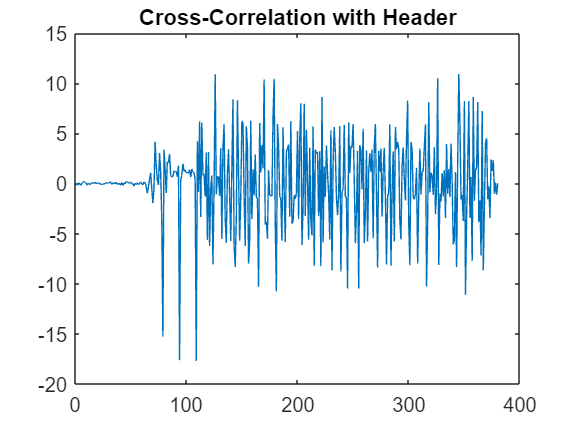

%% Find Start of Packet with Cross-Correlation

received_symbols = symbs;
xc = xcorr(received_symbols, key);
xc = xc(length(received_symbols):end); % since the xcorr has length 2N - 1
% xcorr pads the shorter vector with zeros at the front

plot(xc)
title("Cross-Correlation with Header")

figure

% Change to where the cross correlation summed across x samples is greater than 45

peak_xcorr = max(xc);
min_xcorr = min(xc);

if (peak_xcorr < abs(min_xcorr))
    peak_xcorr = -1 * min_xcorr;
    xc = -1 * xc;
    received_symbols = -1 .* received_symbols;
end

first_peak = find(xc > peak_xcorr * 0.9, 1, 'first');

%%% BETTER XCORR FORMULA

n = length(xc);
maxSum = -inf; % Initialize maxSum to negative infinity
index = -1; % Initialize index to -1 in case no such index is found
for i = 1:(n-length(header))
    currentSum = abs(xc(i) + xc(i+length(key)) + xc(i+2*length(key)));
    if currentSum > maxSum
        maxSum = currentSum;
        index = i;
    end
end
first_peak = index

first_peak = 79

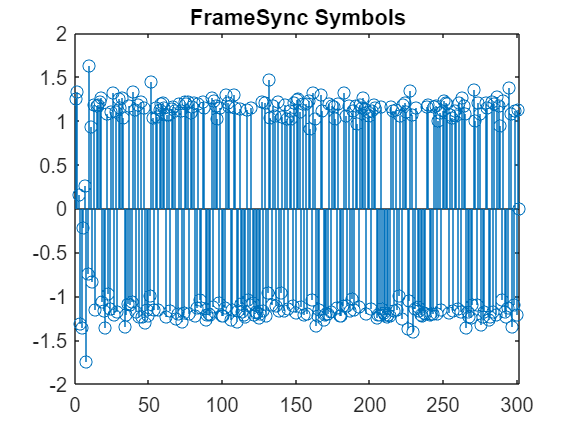


%%%


aligned_symbols = received_symbols(first_peak:end);
stem(aligned_symbols)
title("FrameSync Symbols")

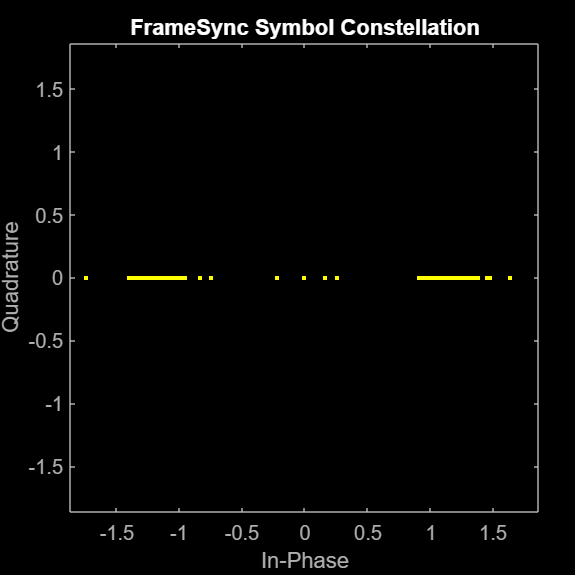

figure

scatterplot(aligned_symbols)
title("FrameSync Symbol Constellation")

%% Extract Aligned Bits

% ideally for this section we'd remove the packet key
aligned_bits = sign(real(aligned_symbols(length(header)+1:end)));
aligned_bits(aligned_bits == -1) = 0;

s = string(aligned_bits);
s = strjoin(s);
s = strrep(s, " ", "");
disp(s);

01000011011011110110111001100111011100100110000101110100011100110010000100100000010100110110100101101101011101010110110001100001011101000110100101101111011011100010000001101001011100110010000001100011011011110110110101110000011011000110010101110100011001010


s_len = length(char(s))

s_len = 257

%% Display Message

inputString = char(s);
binaryString = inputString(1:end-mod(length(inputString),8));
binaryChunks = reshape(binaryString, 8, []).';
asciiChars = char(bin2dec(binaryChunks)).';
disp(asciiChars);

Congrats! Simulation is complete
